## **Progettazione dell'osservatore**

L’obiettivo sta nel progettare un osservatore di stato, nell’ipotesi in cui lo stato da osservare è $x_2$. Per la seguente trattazione verra considerato il caso in cui il controllore è quello progettato tramite tecnica **LQR **e successivamente il caso con **LQI**, scelto da noi come il miglior controllore per la realtà fisica studiata. La scelta di analizzare anche le prestazioni ottenute con l'LQR, nonostante non sia il controllore scelto è dovuta a motivazioni di carattere comparativo tra i due approcci, nonostante quello proposto sia comunque basato su LQI.

## **Progettazione dell'osservatore sulla base dell'LQR**

In funzione della costruzione di un osservatore, anzitutto va effettuato il controllo sull’osservabilità del sistema. A tal proposito, si calcola la matrice di osservabilità $W_o$ dopo aver linearizzato il sistema intorno a $x_e$. 

clear all
close all
A=[0 1; 9.81 -0.1];
B=[0; 1];
C=[1 0];
D=0;

Wo = [C;C*A];
rank(Wo);

A questo punto bisogna considerare uno dei controllori individuati nel **WP1**, nello specifico si prende quello LQR:


$$u = -92.0469x_1- 14.4179x_2+92.0469\pi$$


Noto il controllore di partenza, quindi i valori di $K$, in questo caso, si possono utilizzare tali parametri insieme alle matrici $A$ e $B$ del sistema linearizzato intorno a $x_e$ per individuare i poli del sistema a ciclo chiuso, nello specifico si ha 

K =  [92.0469   14.4179];

P = eig(A - B * K)

P =   -7.2589 + 5.4355i
  -7.2589 - 5.4355i


Noti i poli, è fondamentale costruire un osservatore caratterizzato da poli a ciclo chiuso più veloci di quelli del sistema, quindi si procede con un pole placement per ottenere la matrice $L$ per il termine correttivo dell’osservatore a partire da poli desiderati.

P_obs = [-900 -1000];
L = place(A.',C.',P_obs);
L=L.';

Per quanto riguarda il piazzamento dei poli, abbiamo voluto porci nella condizione in cui il sistema osservatore sia molto più veloce del sistema osservato, interpretandolo con almeno 20 volte. Testando questi valori, però, abbiamo notato alcuni problemi nell'osservabilità della variabile $x_2$, di conseguenza il valore è stato spinto per raggiungere prestazioni adeguate, in particolare i valori considerati sono:

$\omega=948$ e $\zeta=1$ che corrispondono ad un sistema circa 100 volte più veloce di quello da osservare.

Una volta ottenuto il parametro $L$, si può passare allo schema Simulink:

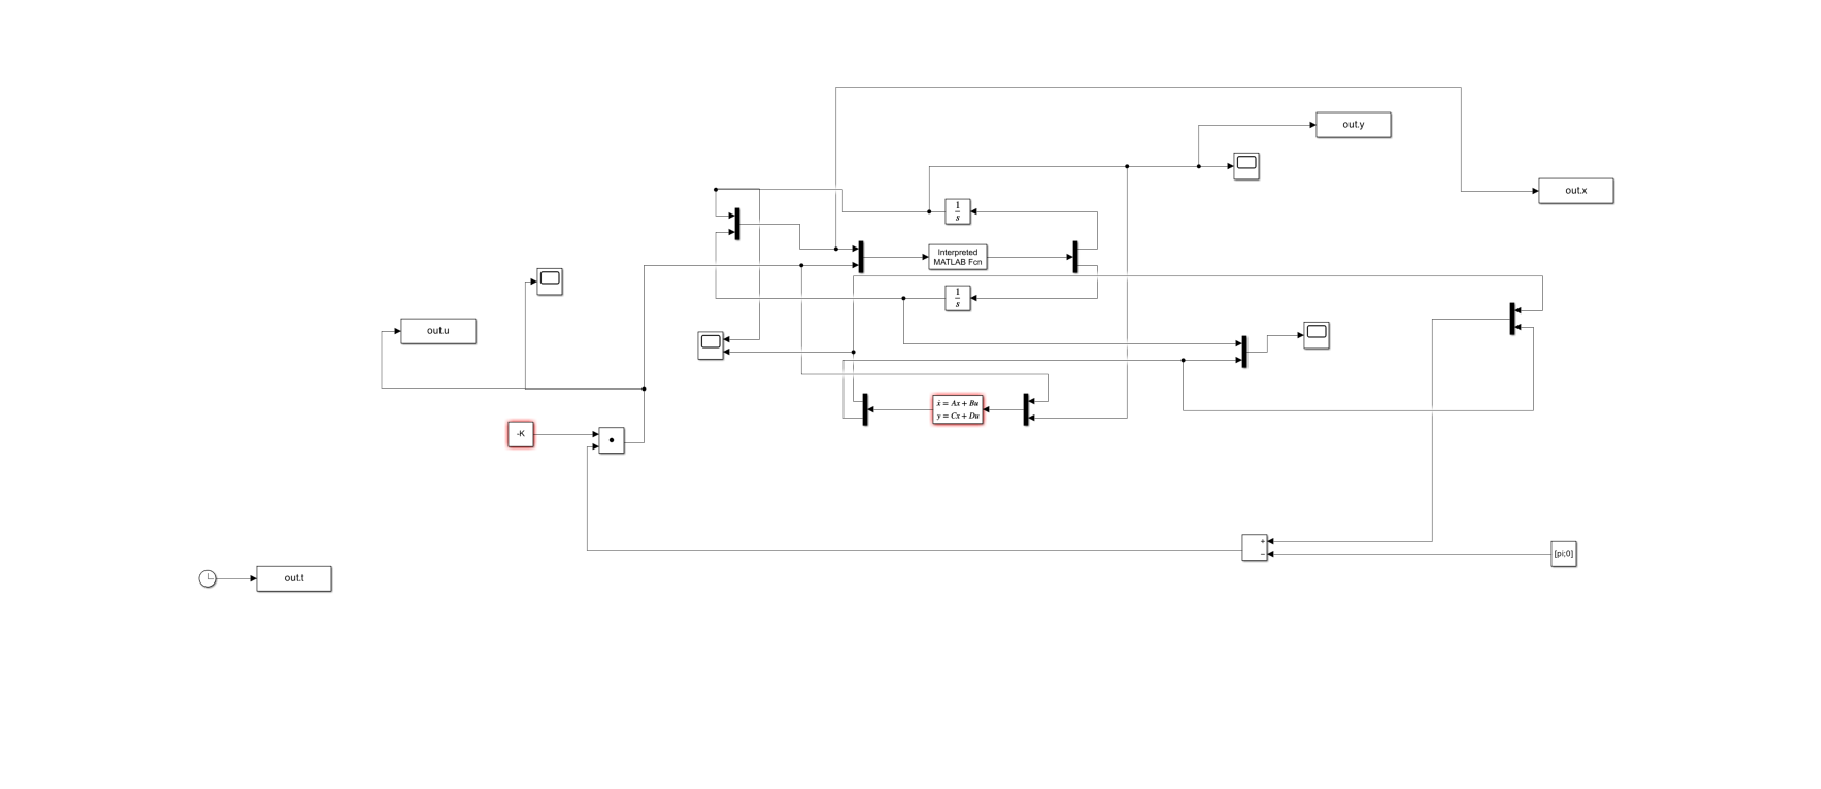

imshow(imread("img/LQR_observer.png"))

## **Simulazione**

simOut = sim("OBS_s_inv.slx", 'SimulationMode', 'normal');

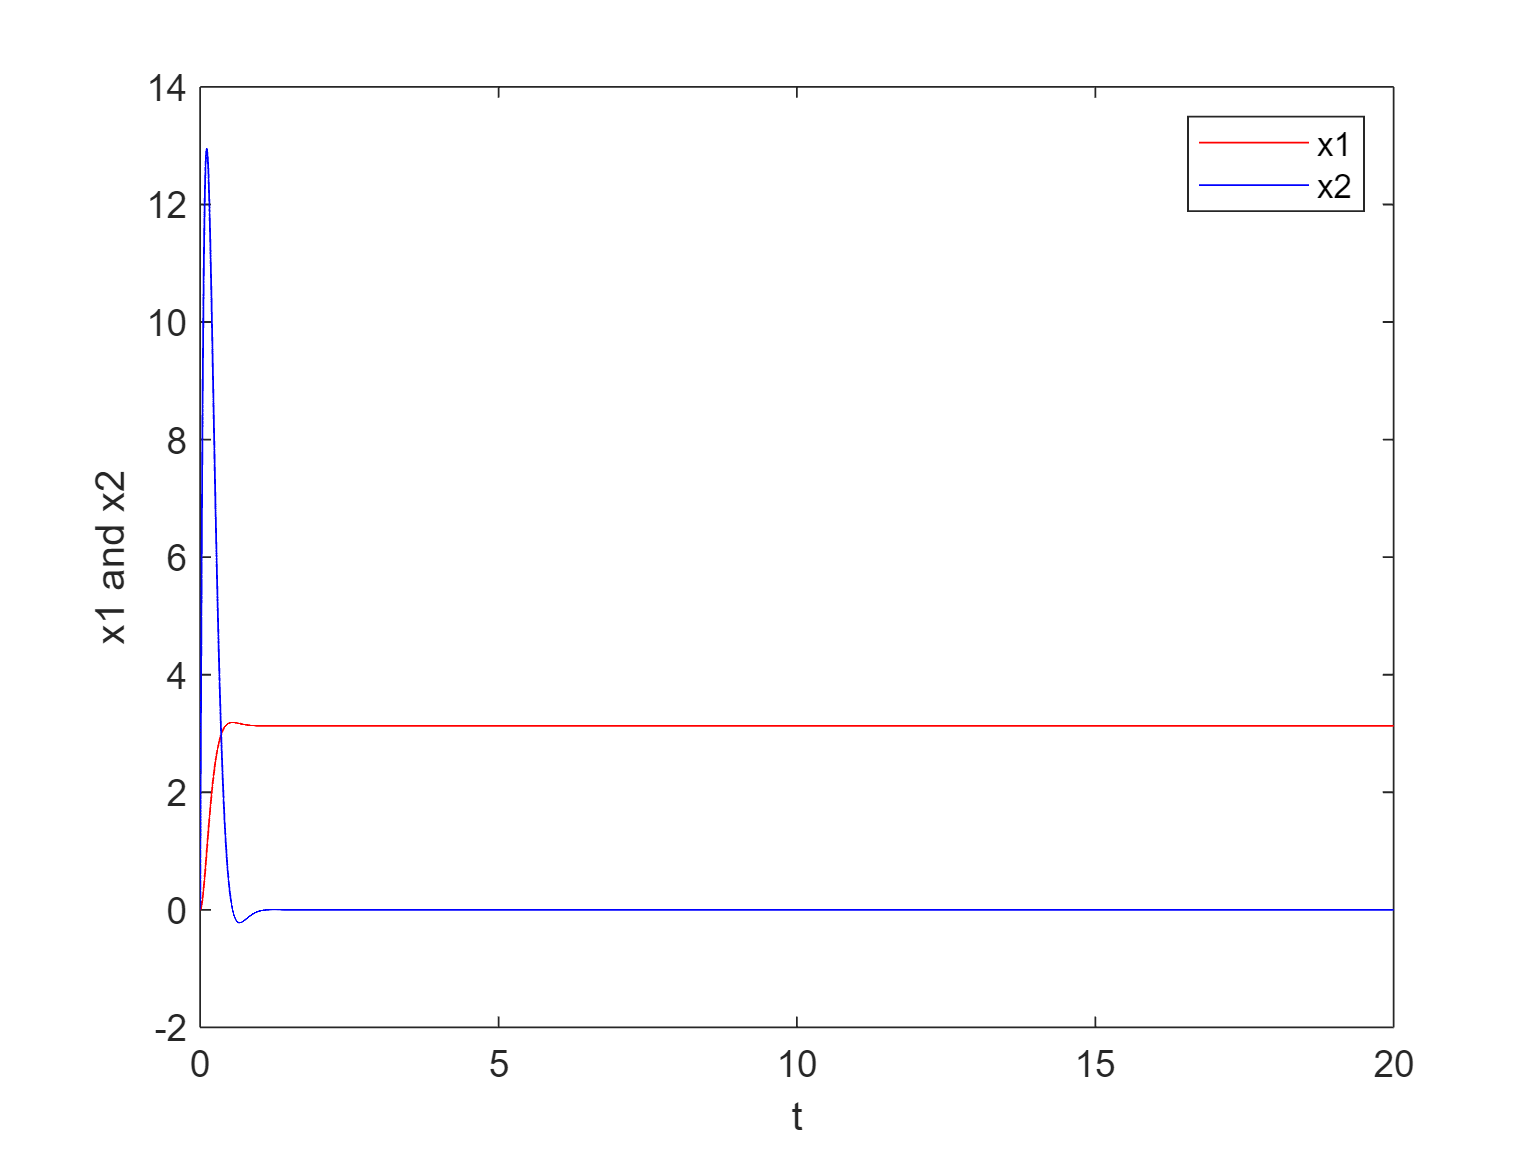

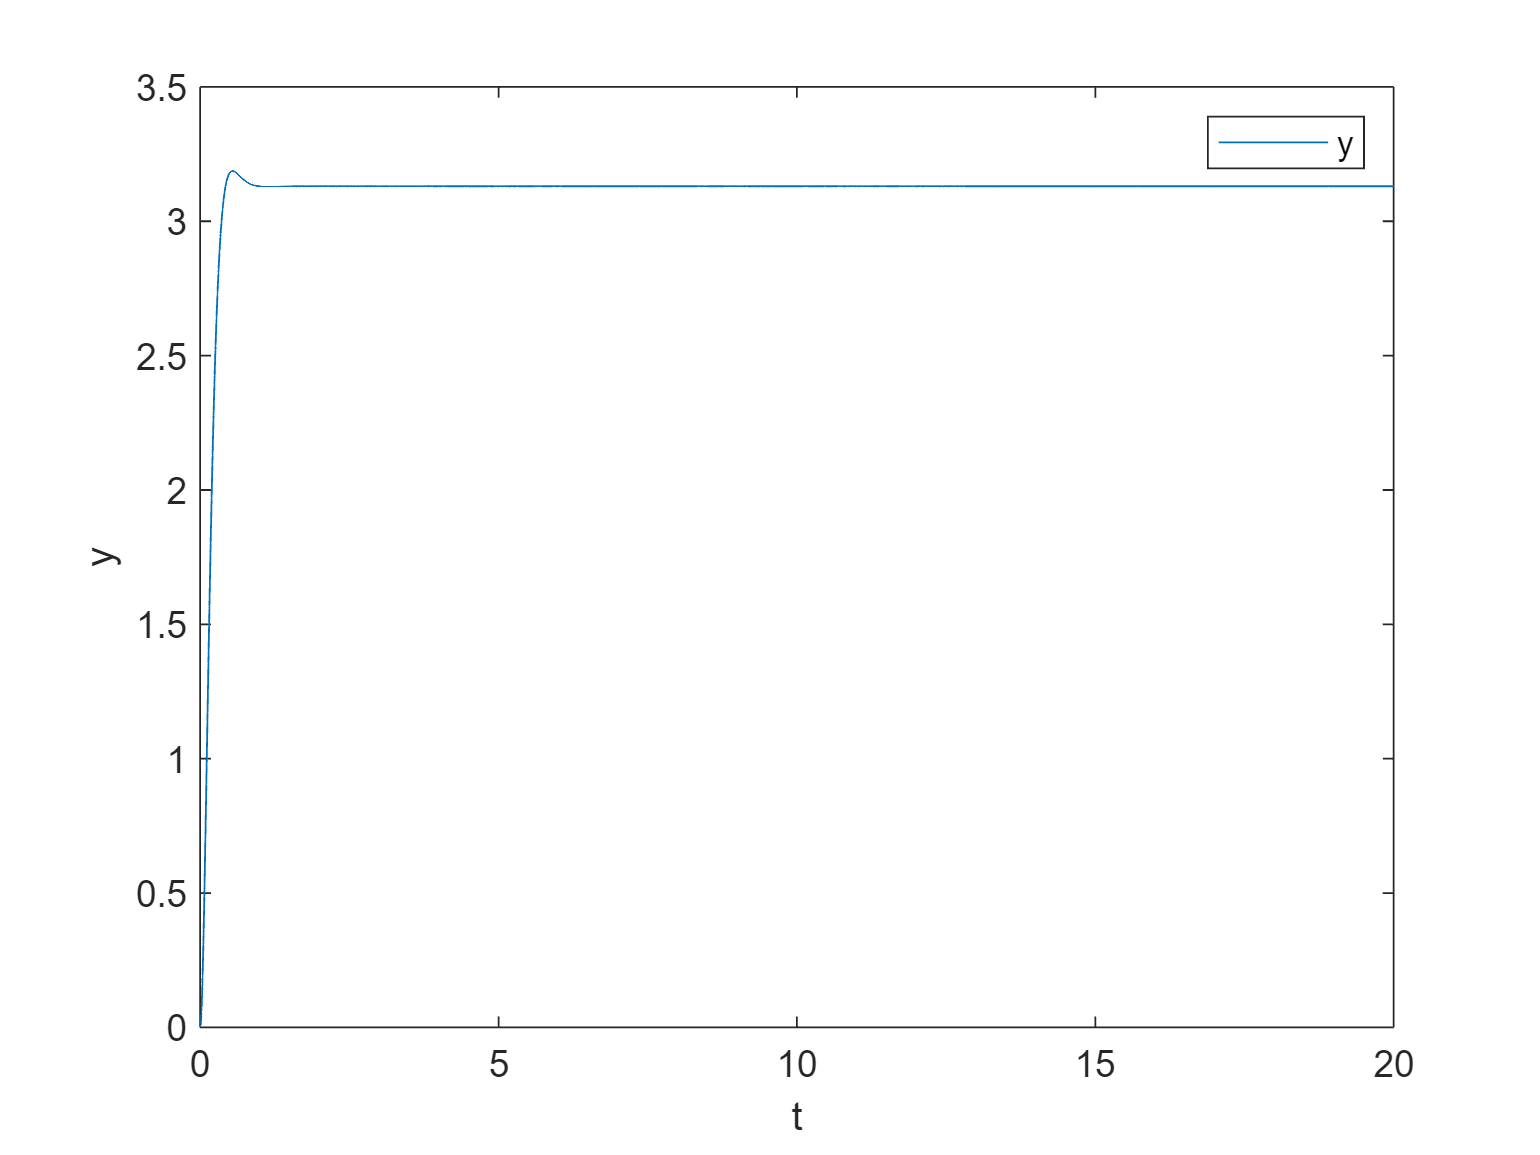

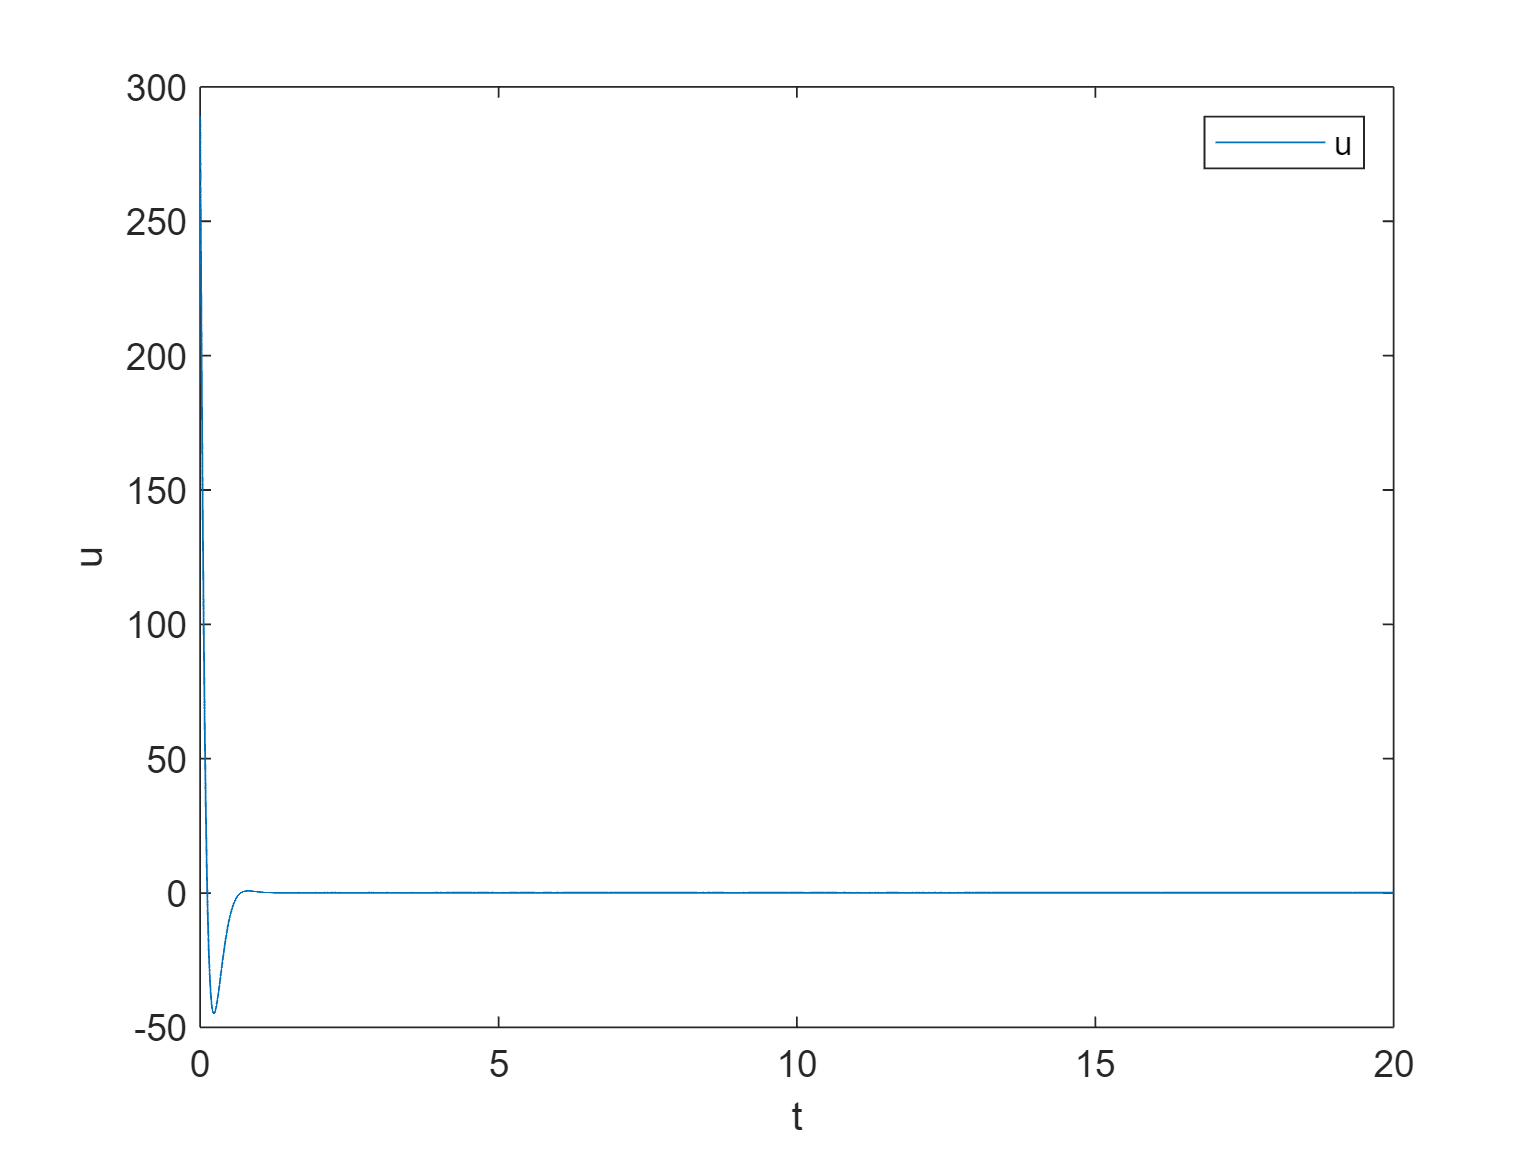

Step Information for the Output:
         RiseTime: 0.2541
    TransientTime: 0.3857
     SettlingTime: 0.3857
      SettlingMin: 2.8175
      SettlingMax: 3.1869
        Overshoot: 1.8144
       Undershoot: 0
             Peak: 3.1869
         PeakTime: 0.5432




% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults_LQR(simOut,1);

Come notiamo anche con l'aggiunta dell'osservatore il sistema raggiunge il regime correttamente, con prestazioni comparabili a quelle del sistema senza osservatore, ma con il costo in più di dover progettare l'osservatore con dei poli molto veloci e una risposta finale che non arriva perfettamente a regime a causa della discrepanza tra variabile osservata e reale:

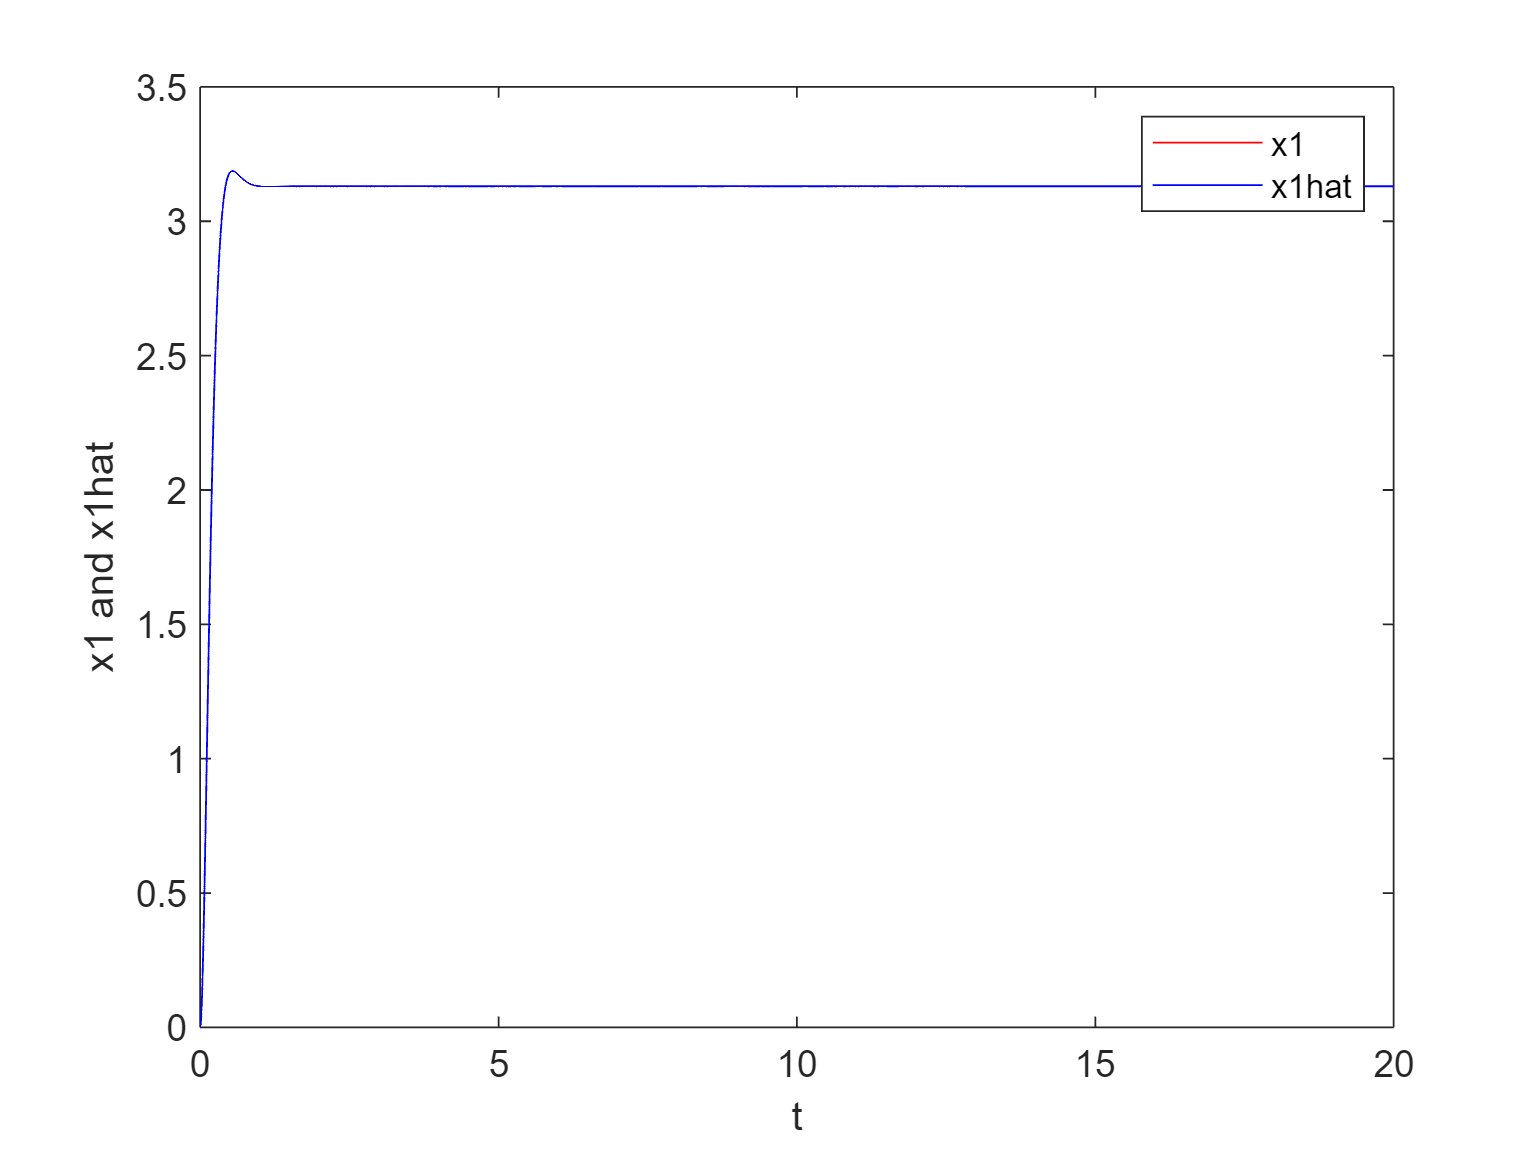

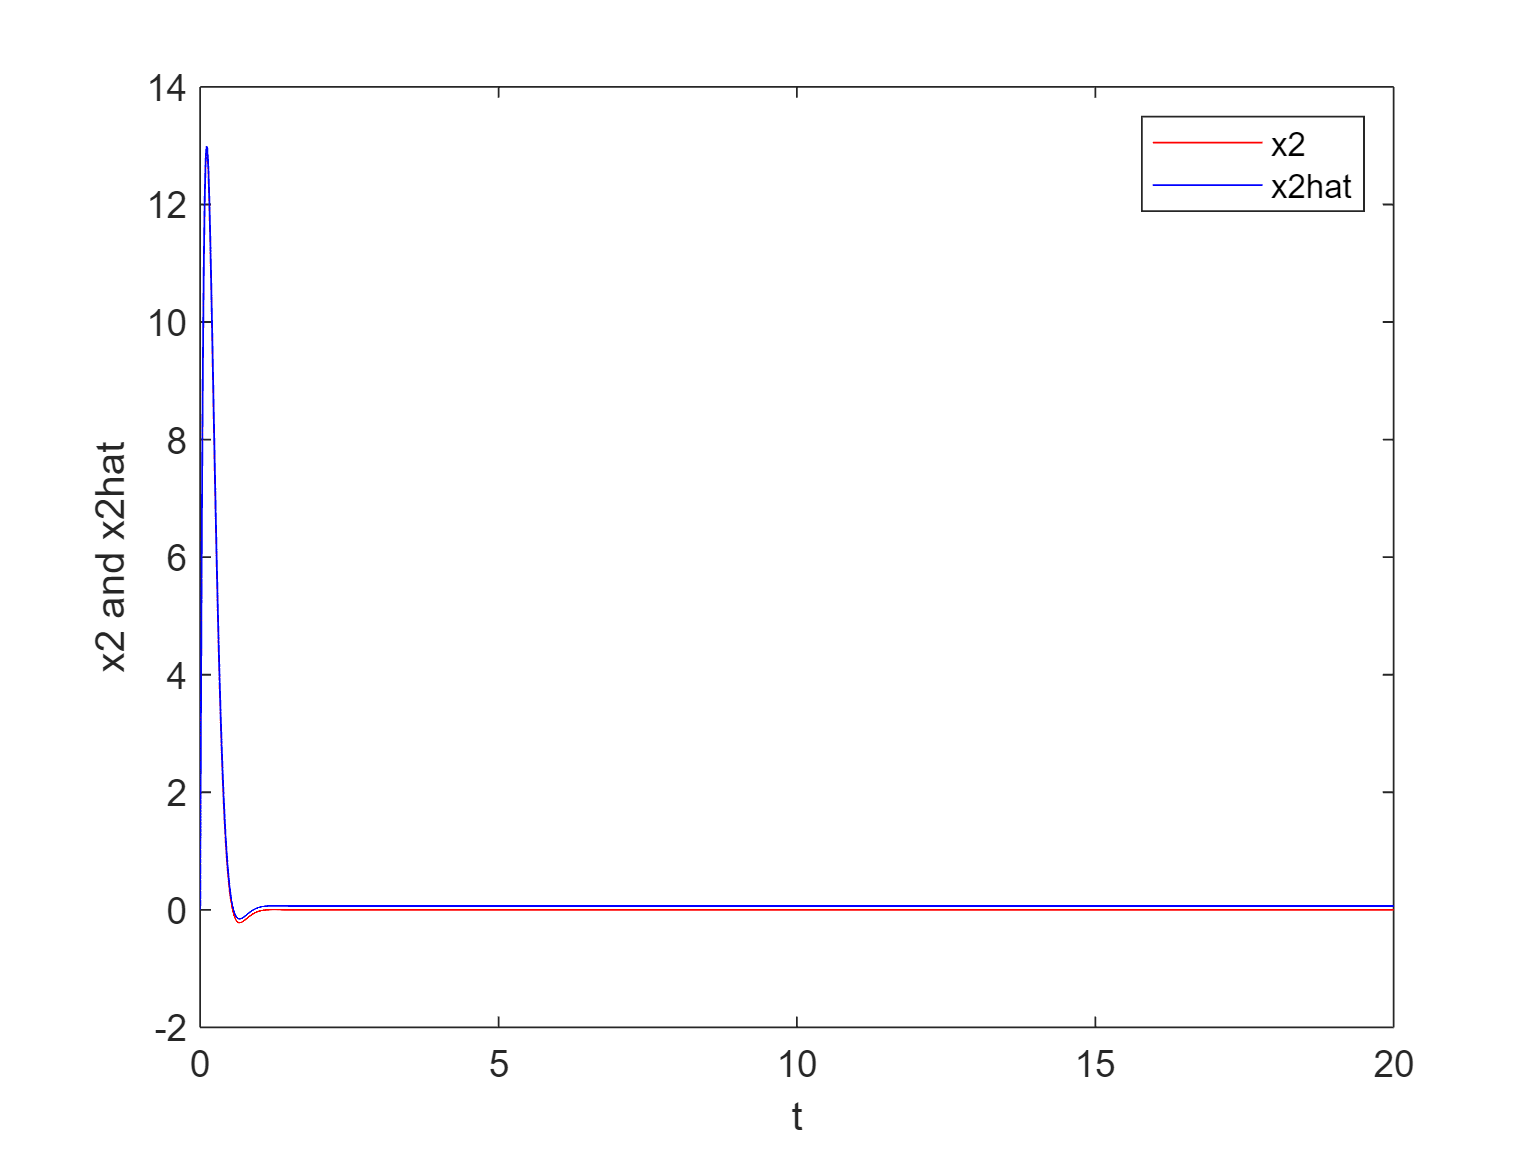

plotDifferences(simOut);

## **Progettazione dell'osservatore sulla base dell'LQI**

Proseguiamo la progettazione di un nuovo osservatore sulla base del miglior controllore da noi scelto, ovvero LQI:


$$u = -99.2881x_1- 15.1289x_2+99.2881x_{1e}-40.8248\int(x_1-r)$$


in cui indichiamo $x_{1e}$ a differenza del caso precedente, perchè a causa del disturbo, modifichiamo il punto di equilibrio, come nei casi precedenti, per cercare di abbatterlo più velocemente data la periodicità del sistema.

Noto il controllore di partenza, quindi i valori di $K$, in questo caso, si possono utilizzare tali parametri insieme alle matrici $A$ e $B$ del sistema linearizzato intorno a $x_e$ per individuare i poli del sistema a ciclo chiuso, nello specifico si ha 

K =  [99.2881   15.1289  -40.8248];

p= [-0.4969 + 0.0000i, -7.3660 + 5.2820i, -7.3660 - 5.2820i];

Noti i poli, è fondamentale costruire un osservatore caratterizzato da poli a ciclo chiuso più veloci di quelli del sistema, quindi si procede con un pole placement per ottenere la matrice $L$ per il termine correttivo dell’osservatore a partire da poli desiderati in modo analogo a quanto accaduto per l'LQR. 

P_obs = [-900 -1000];
L = place(A.',C.',P_obs);
L=L.';

Una volta ottenuto il parametro $L$, si può passare allo schema Simulink:

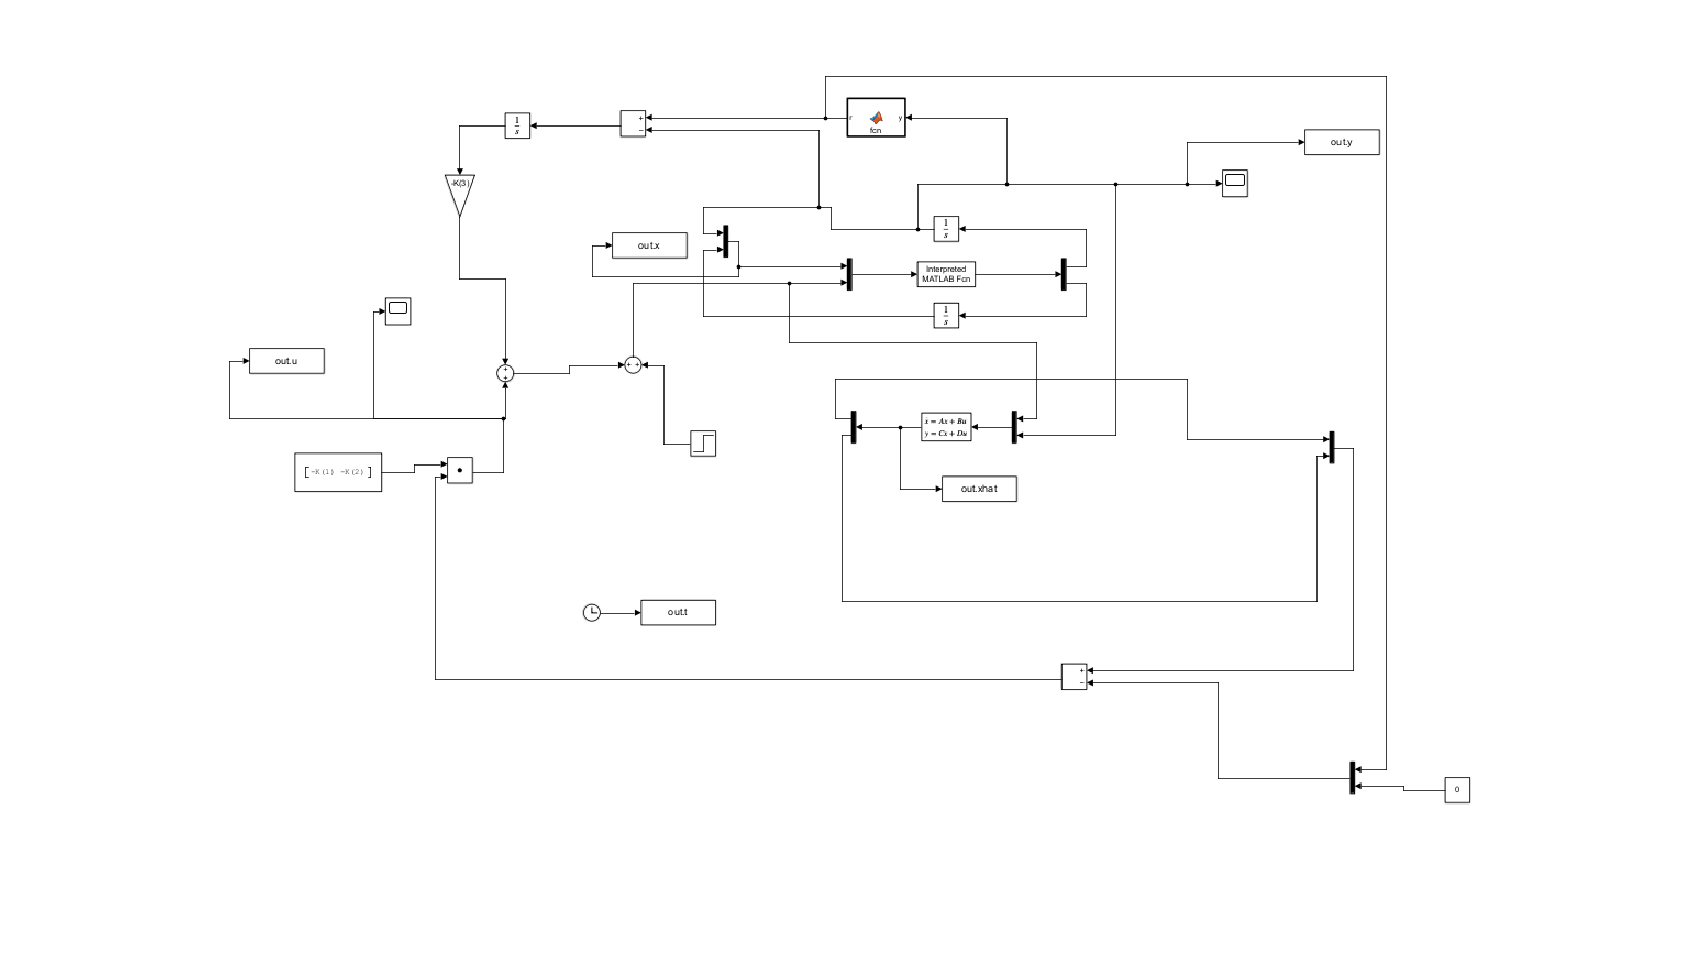

imshow(imread("img/LQI_observer.png"))

## **LQI observer - Simulazione senza disturbo**

Disturbo=0;
simOut = sim("OBS_s_inv_int.slx", 'SimulationMode', 'normal');

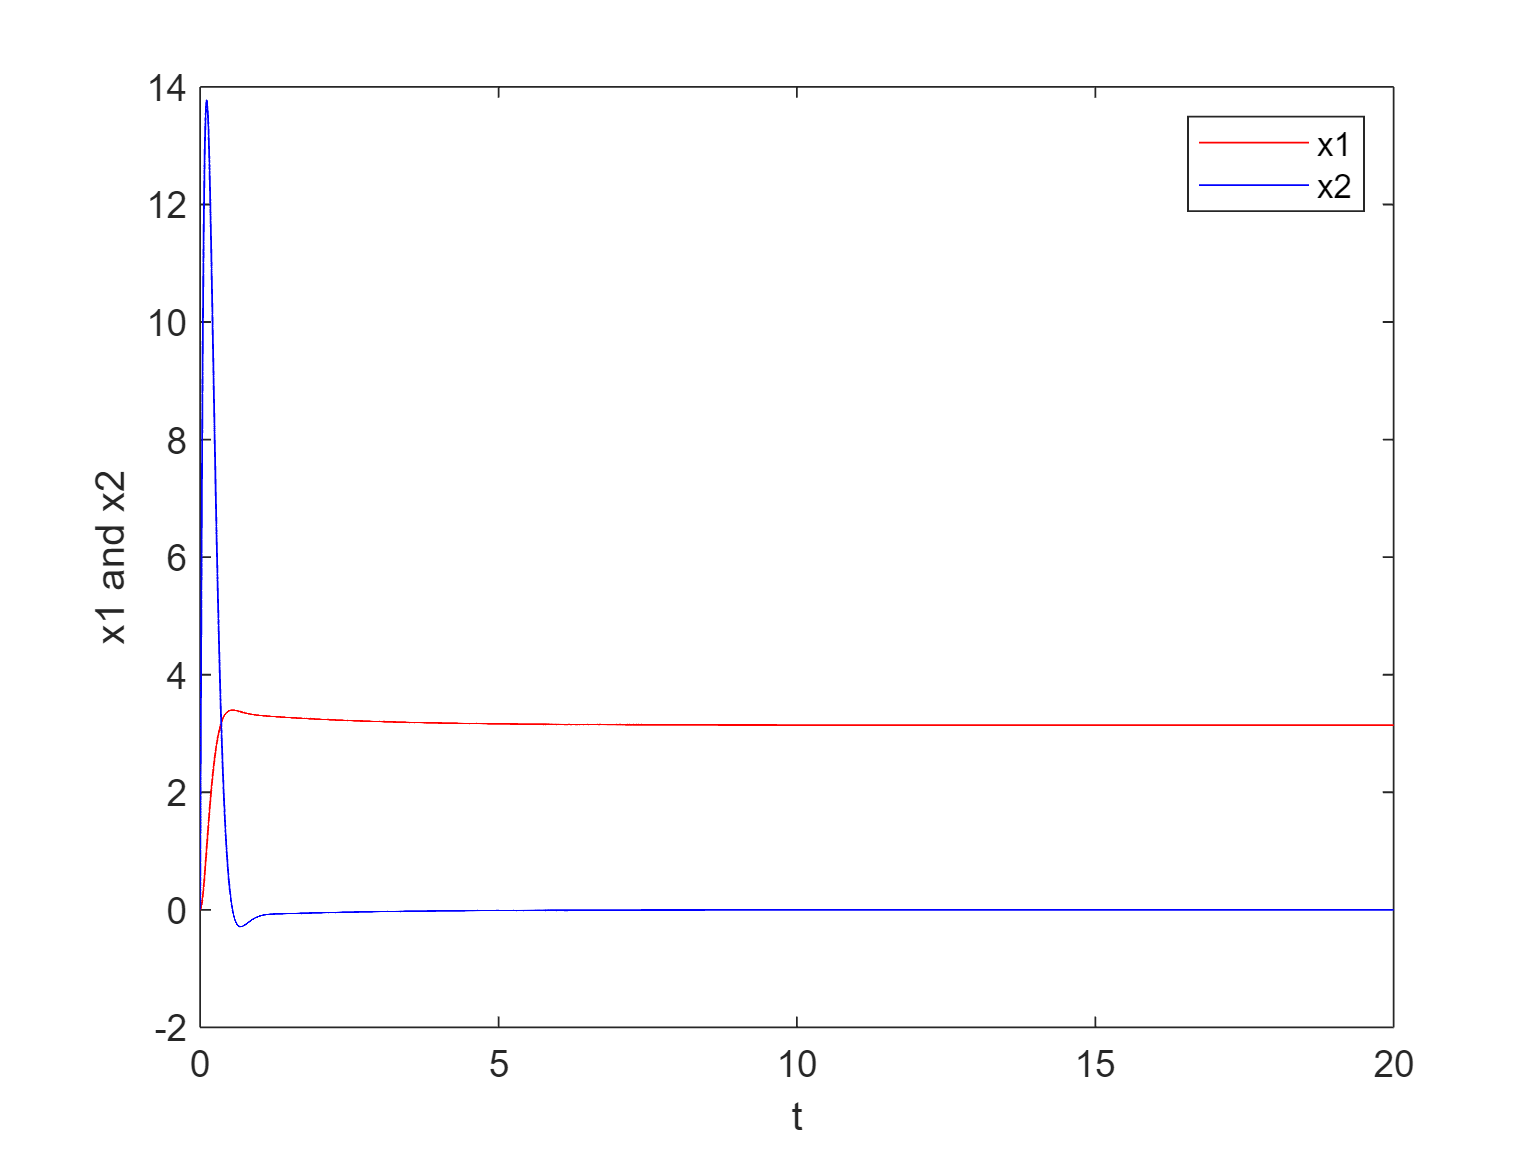

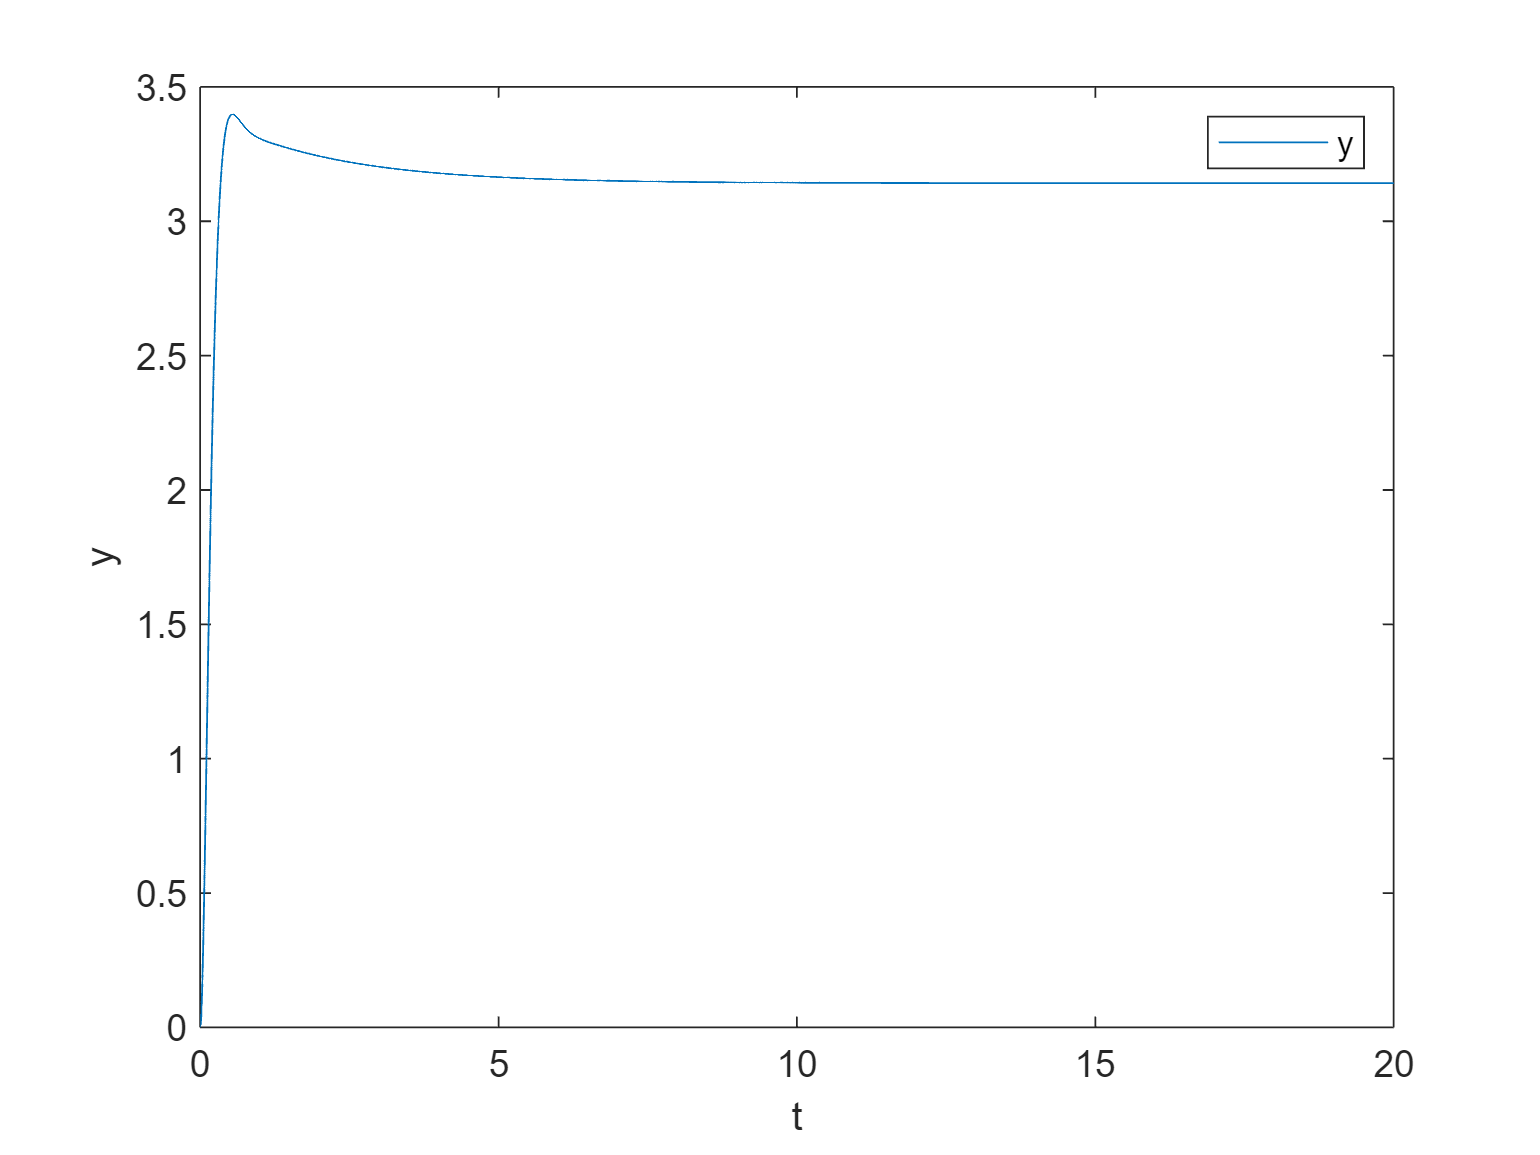

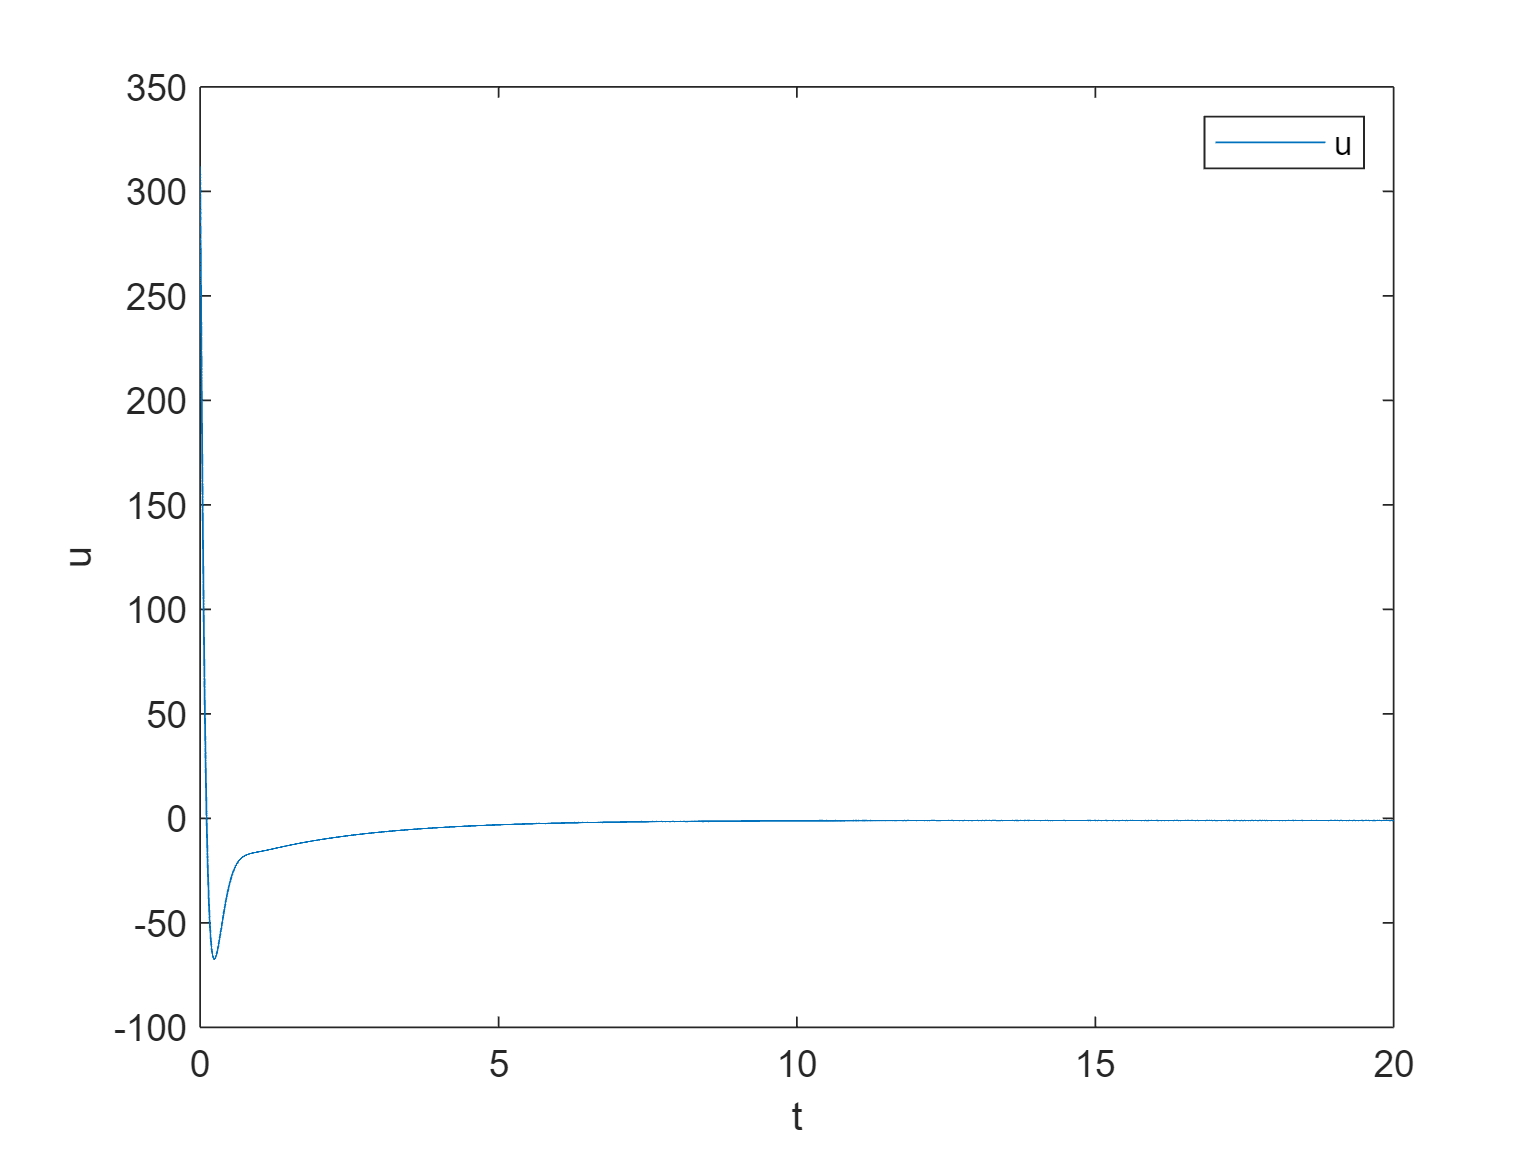

Step Information for the Output:
         RiseTime: 0.2255
    TransientTime: 2.9470
     SettlingTime: 2.9470
      SettlingMin: 2.8276
      SettlingMax: 3.3977
        Overshoot: 8.1504
       Undershoot: 0
             Peak: 3.3977
         PeakTime: 0.5415





% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults_LQR(simOut,1);

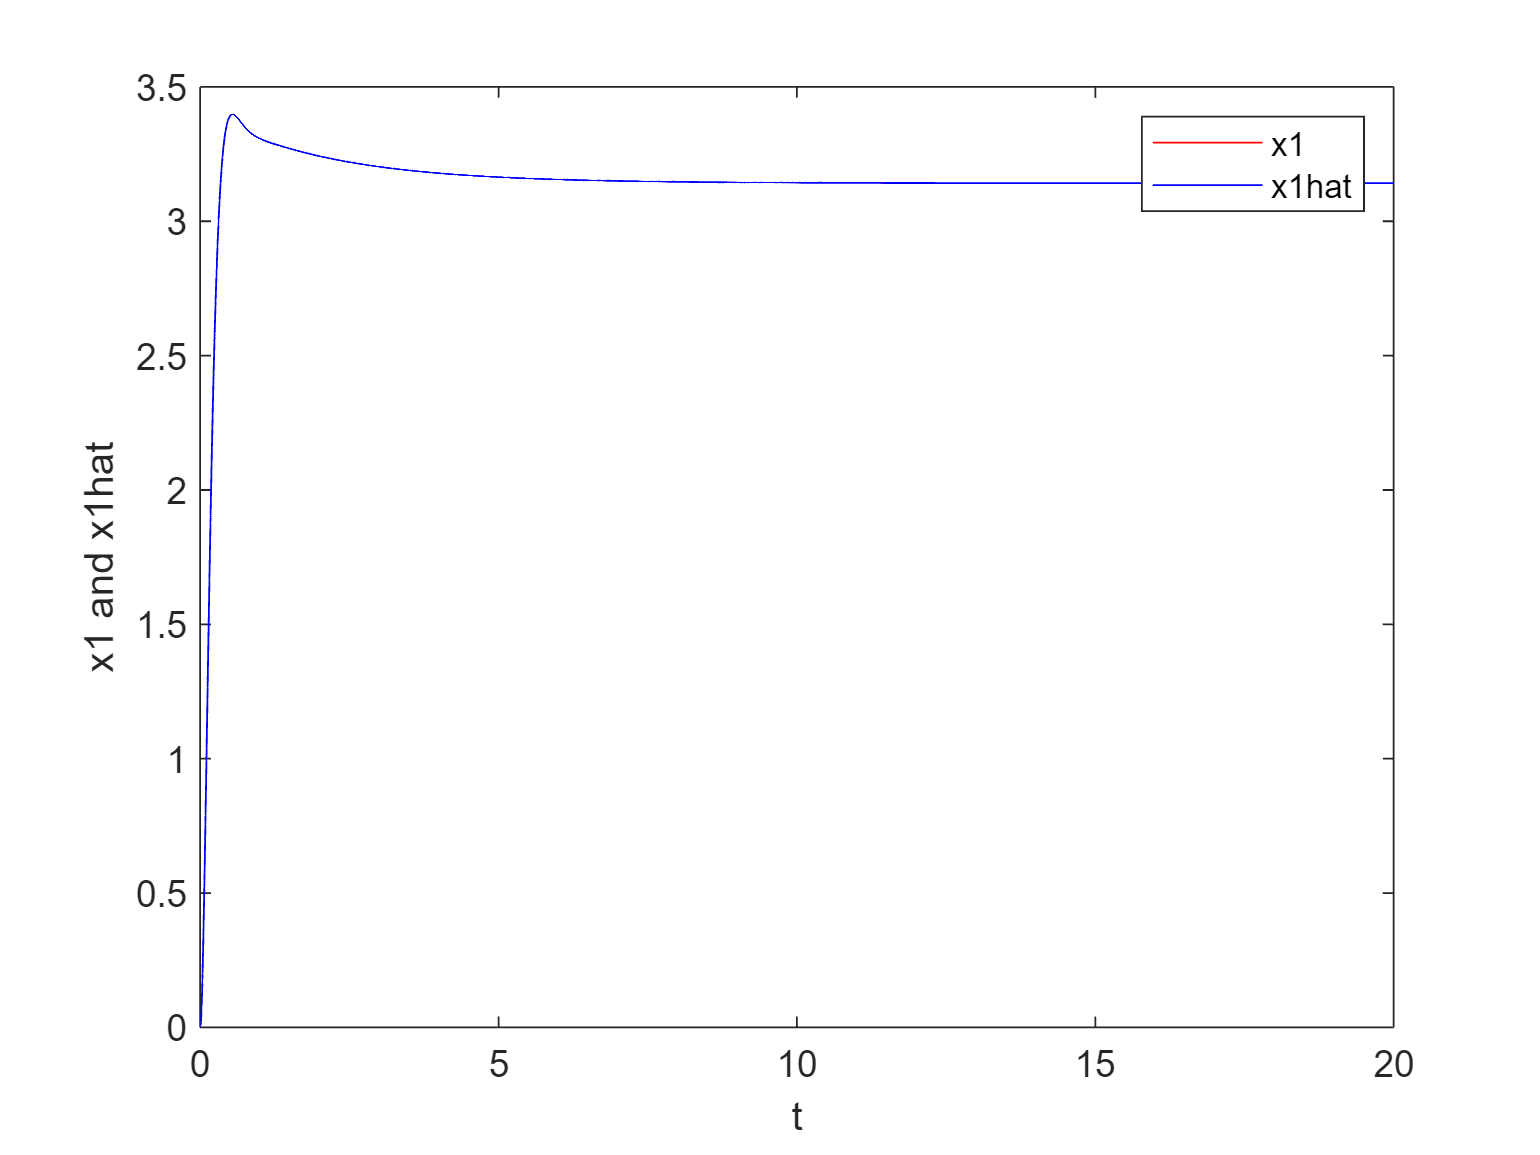

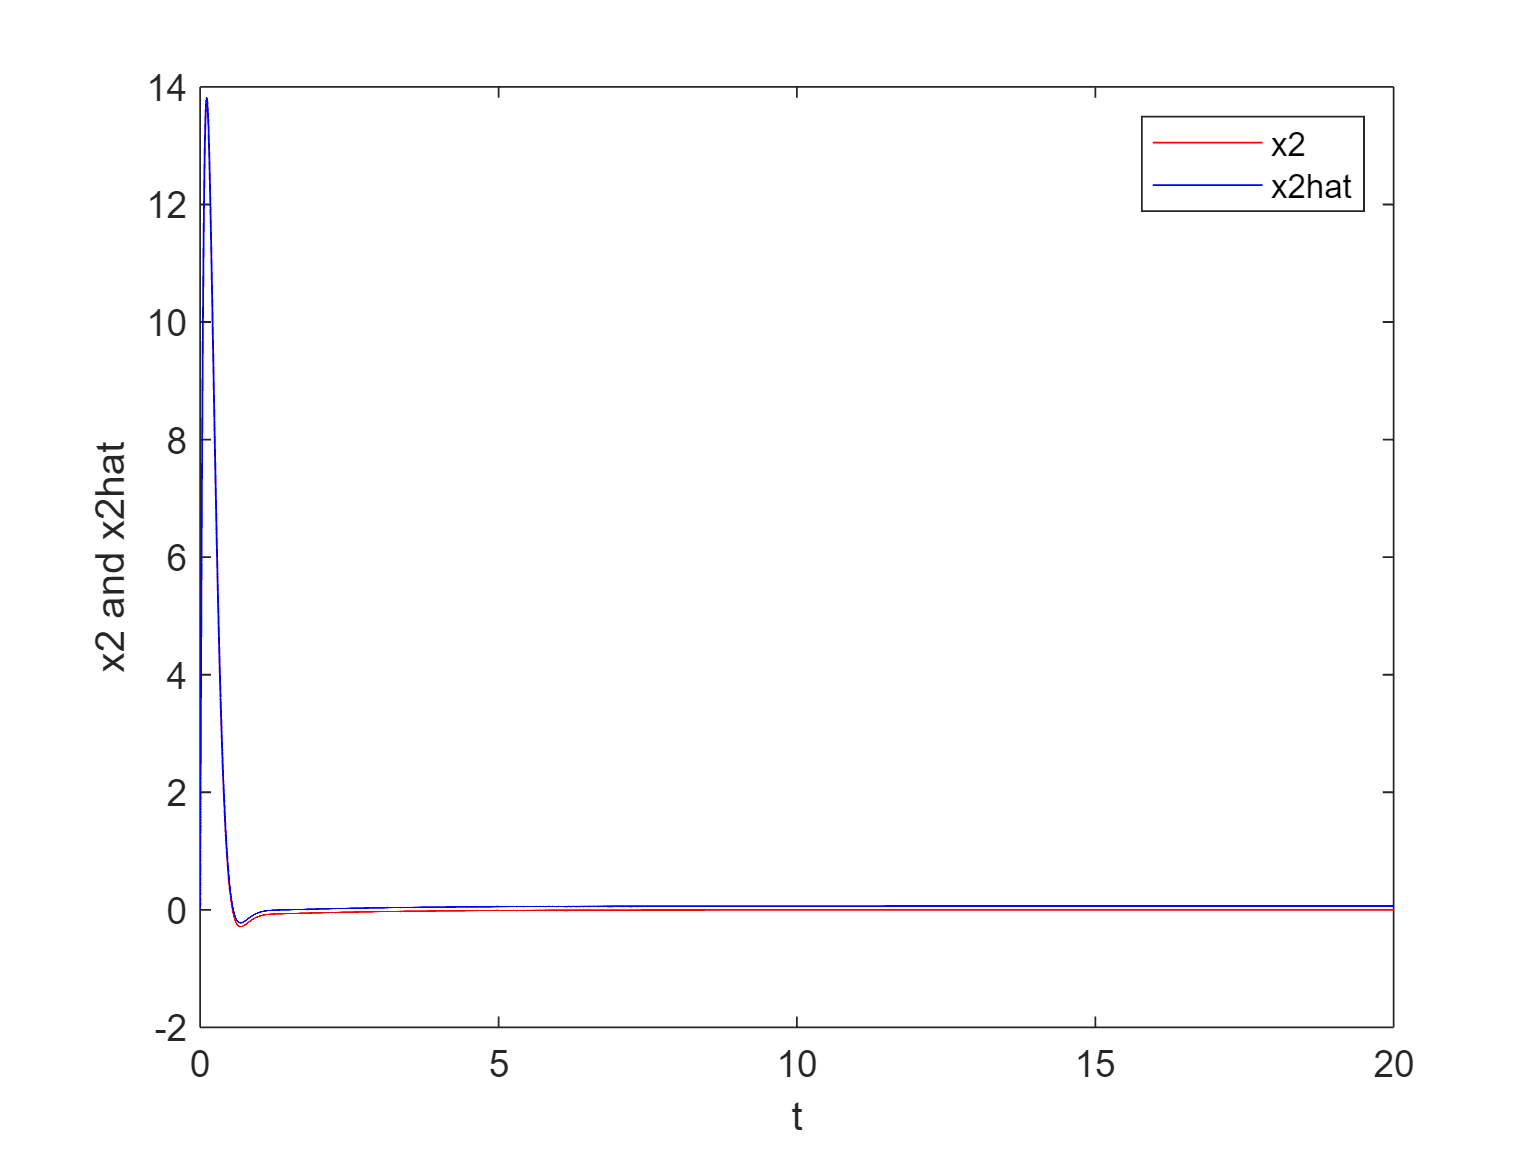

plotDifferences(simOut);

## **LQI observer - Simulazione con disturbo**

Disturbo=50;
simOut = sim("OBS_s_inv_int.slx", 'SimulationMode', 'normal');

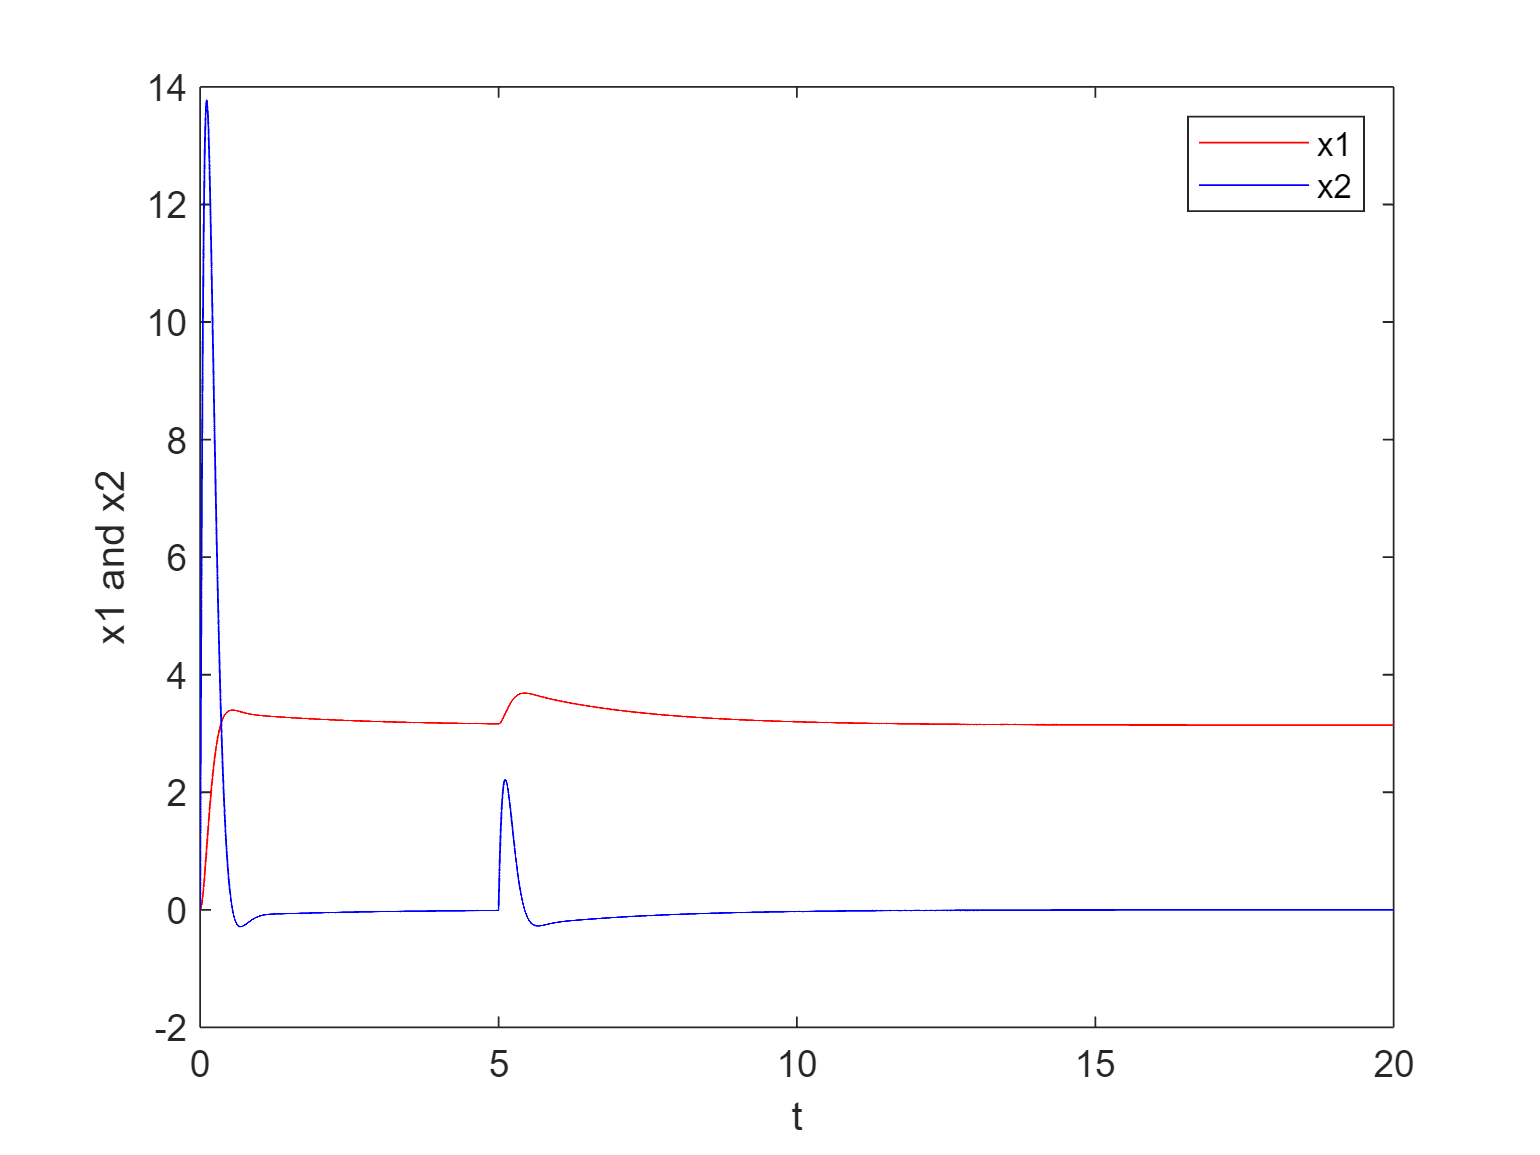

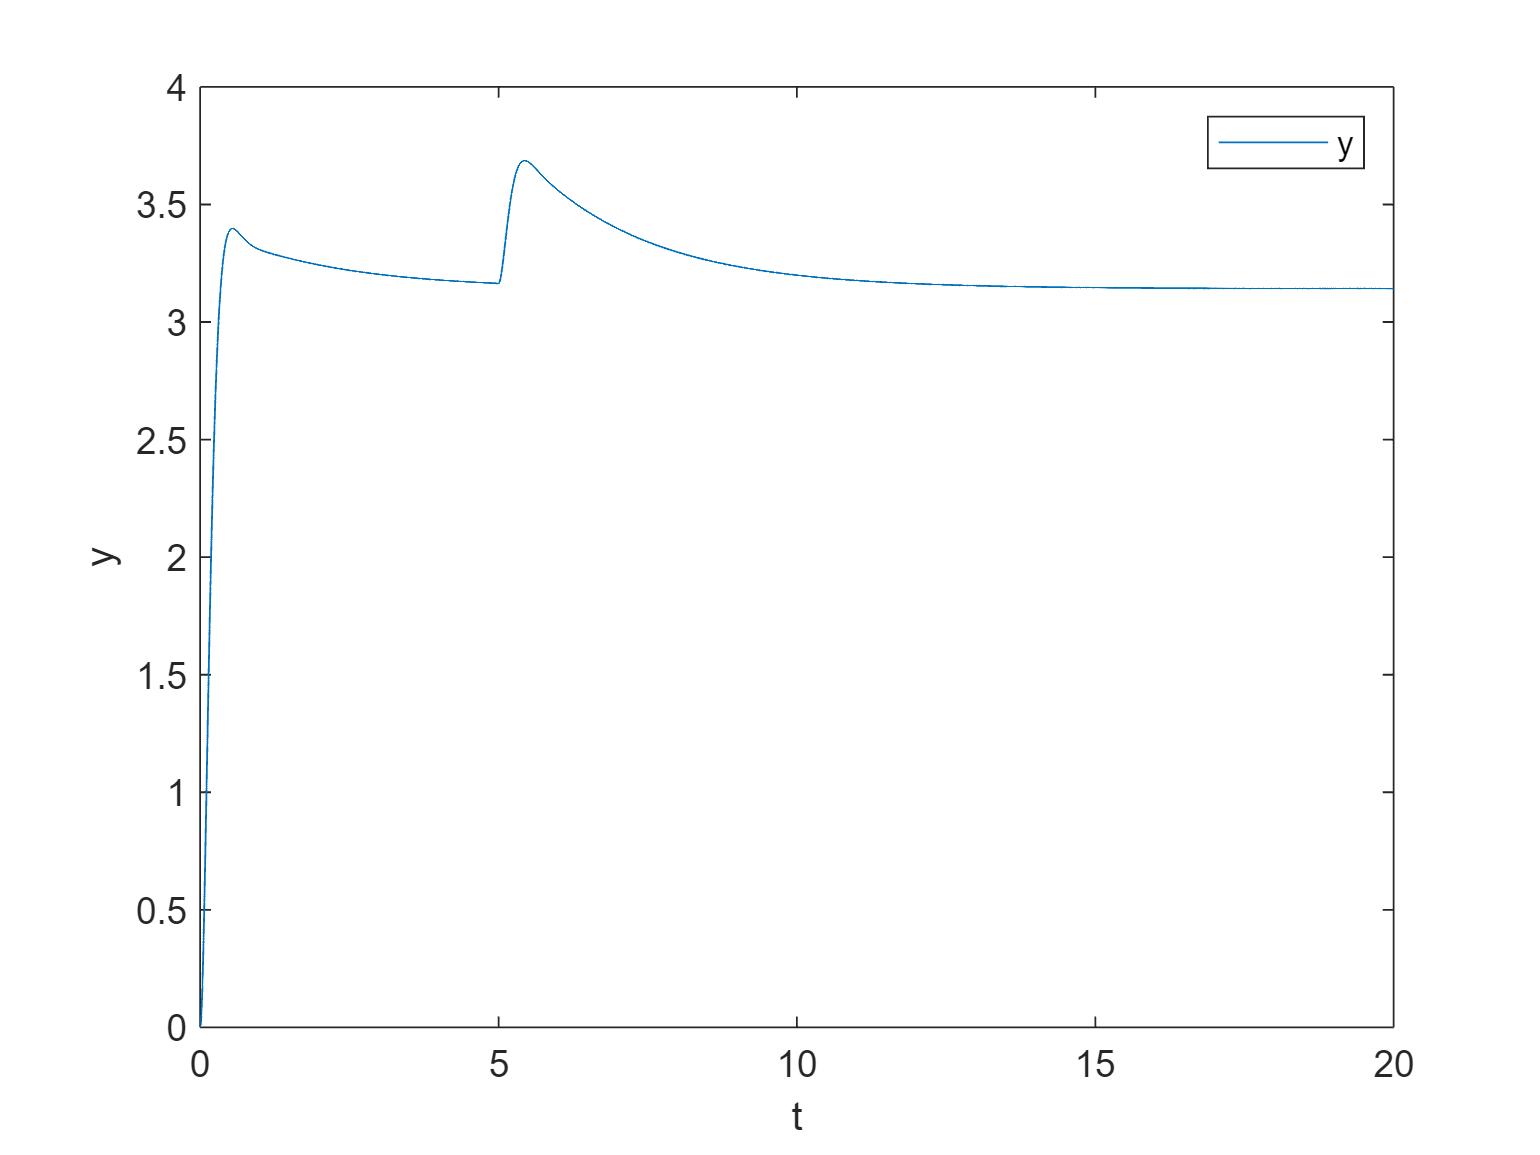

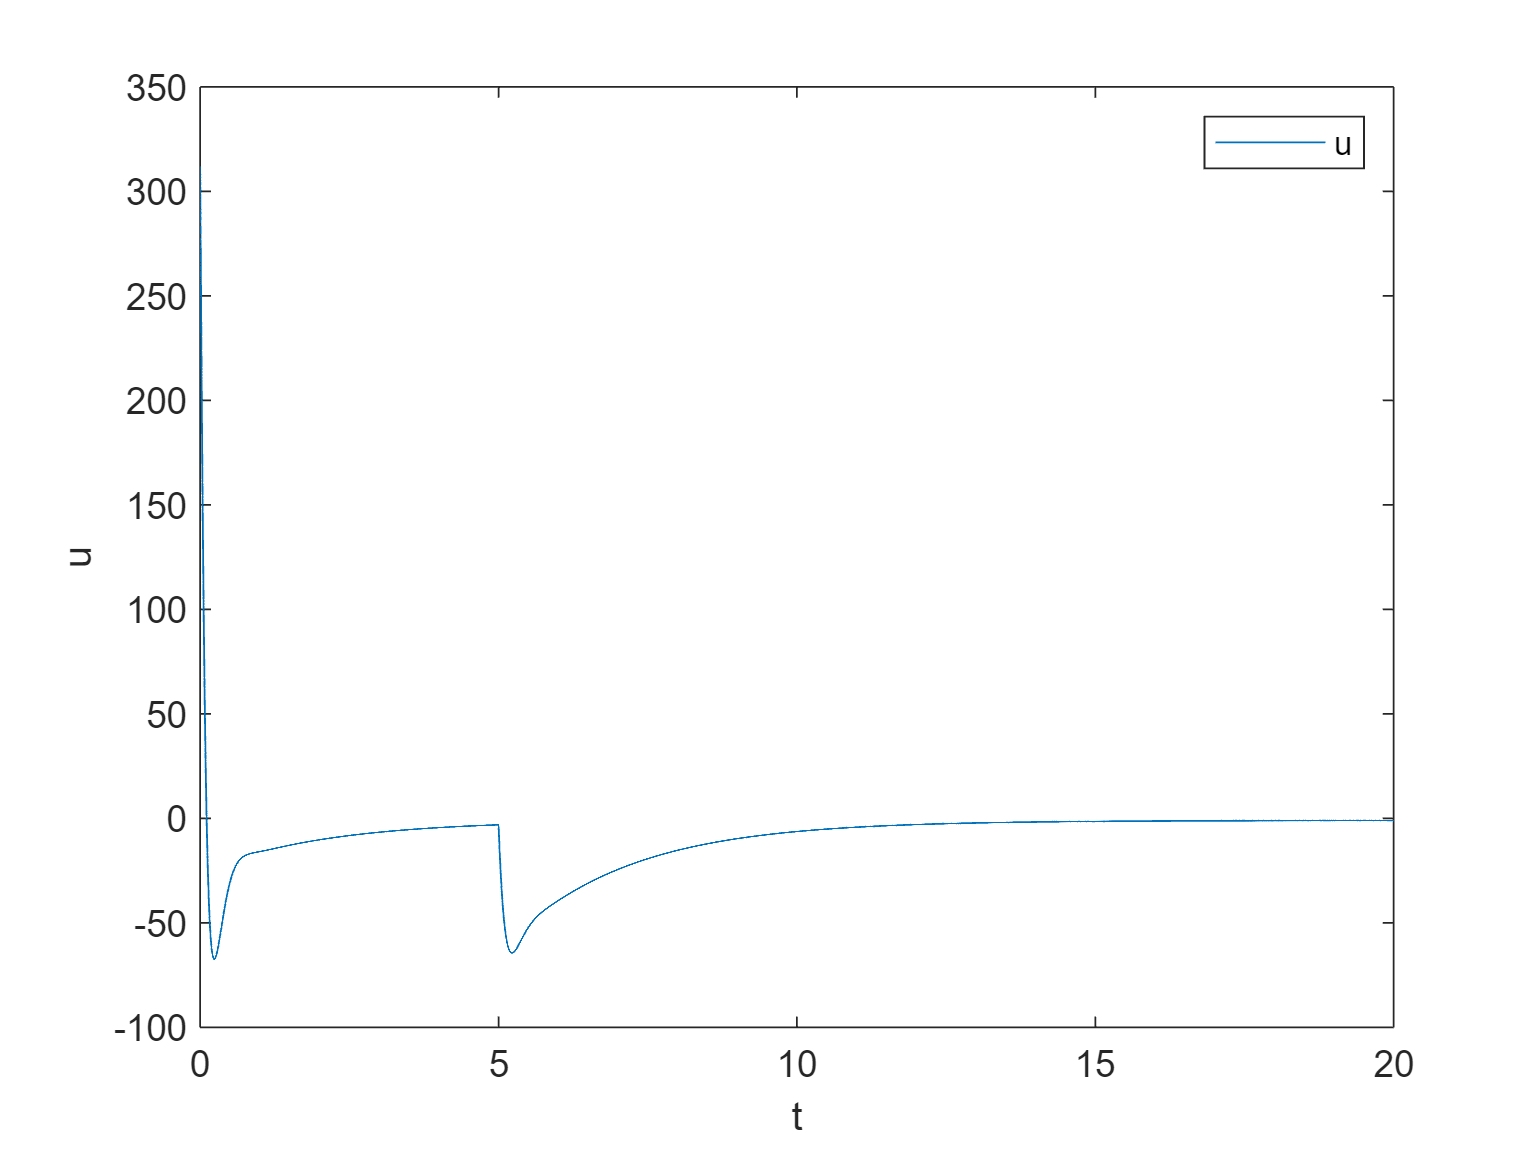

Step Information for the Output:
         RiseTime: 0.2255
    TransientTime: 9.8129
     SettlingTime: 9.8129
      SettlingMin: 2.8314
      SettlingMax: 3.6863
        Overshoot: 17.3226
       Undershoot: 0
             Peak: 3.6863
         PeakTime: 5.4367





% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults_LQR(simOut,1);

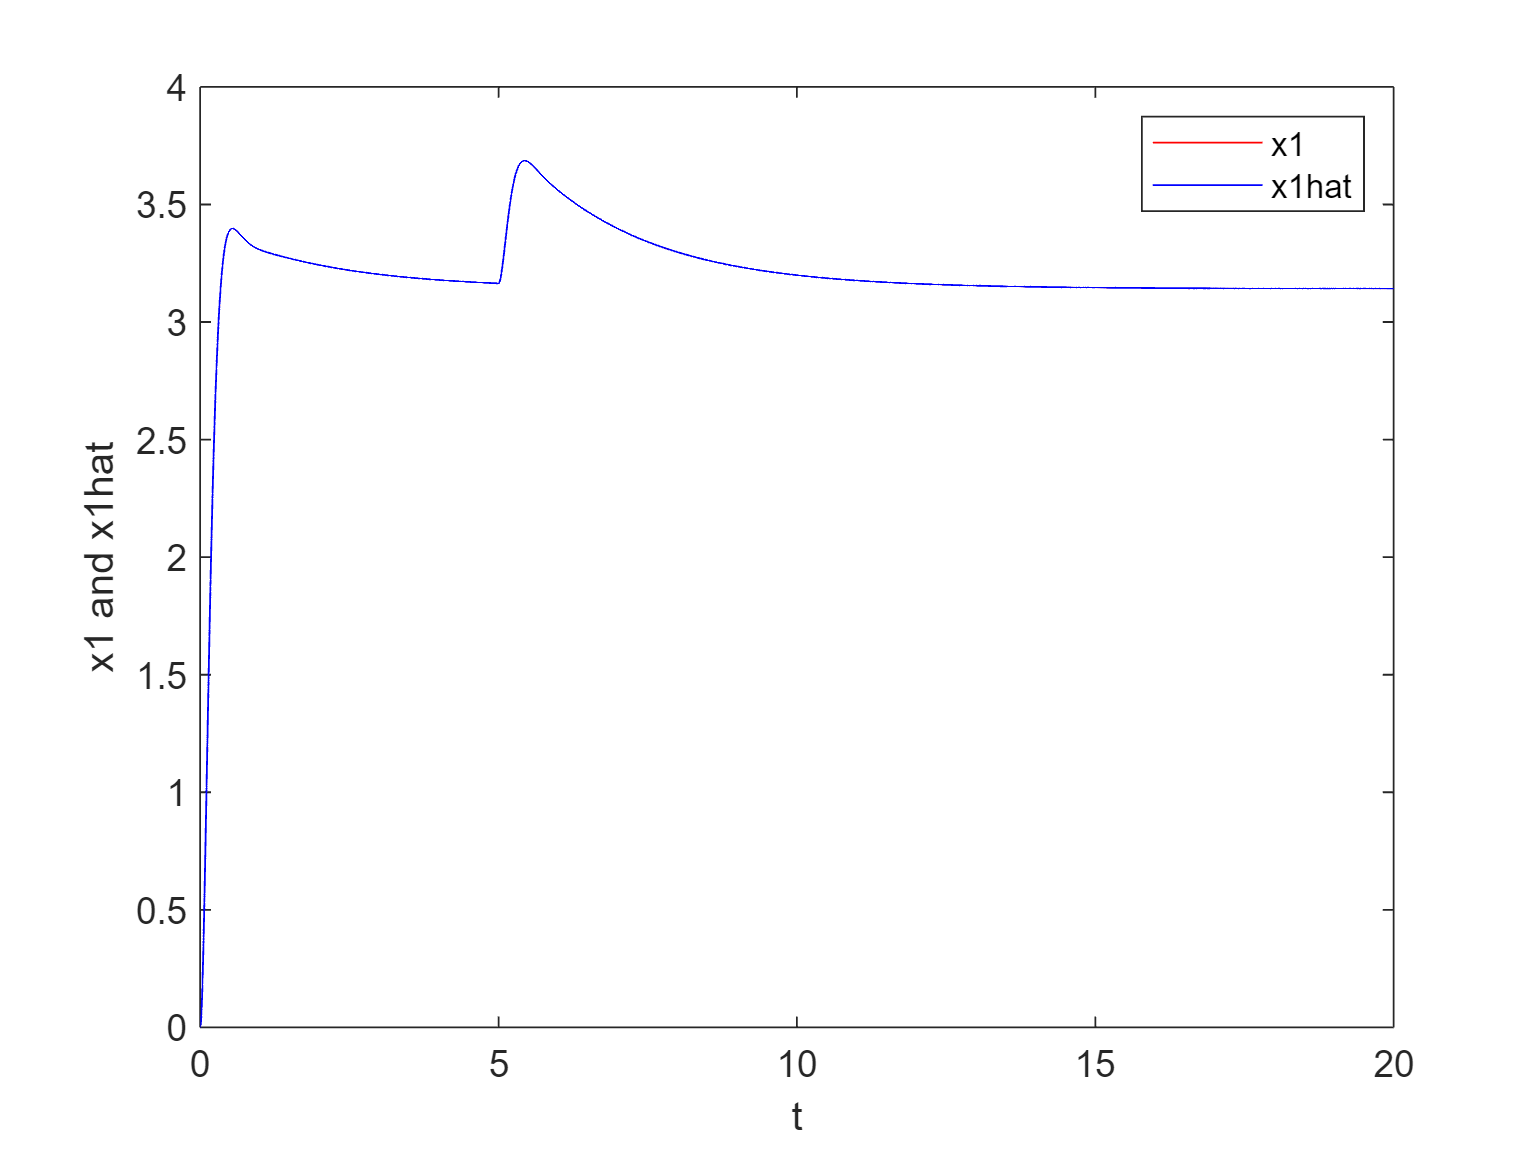

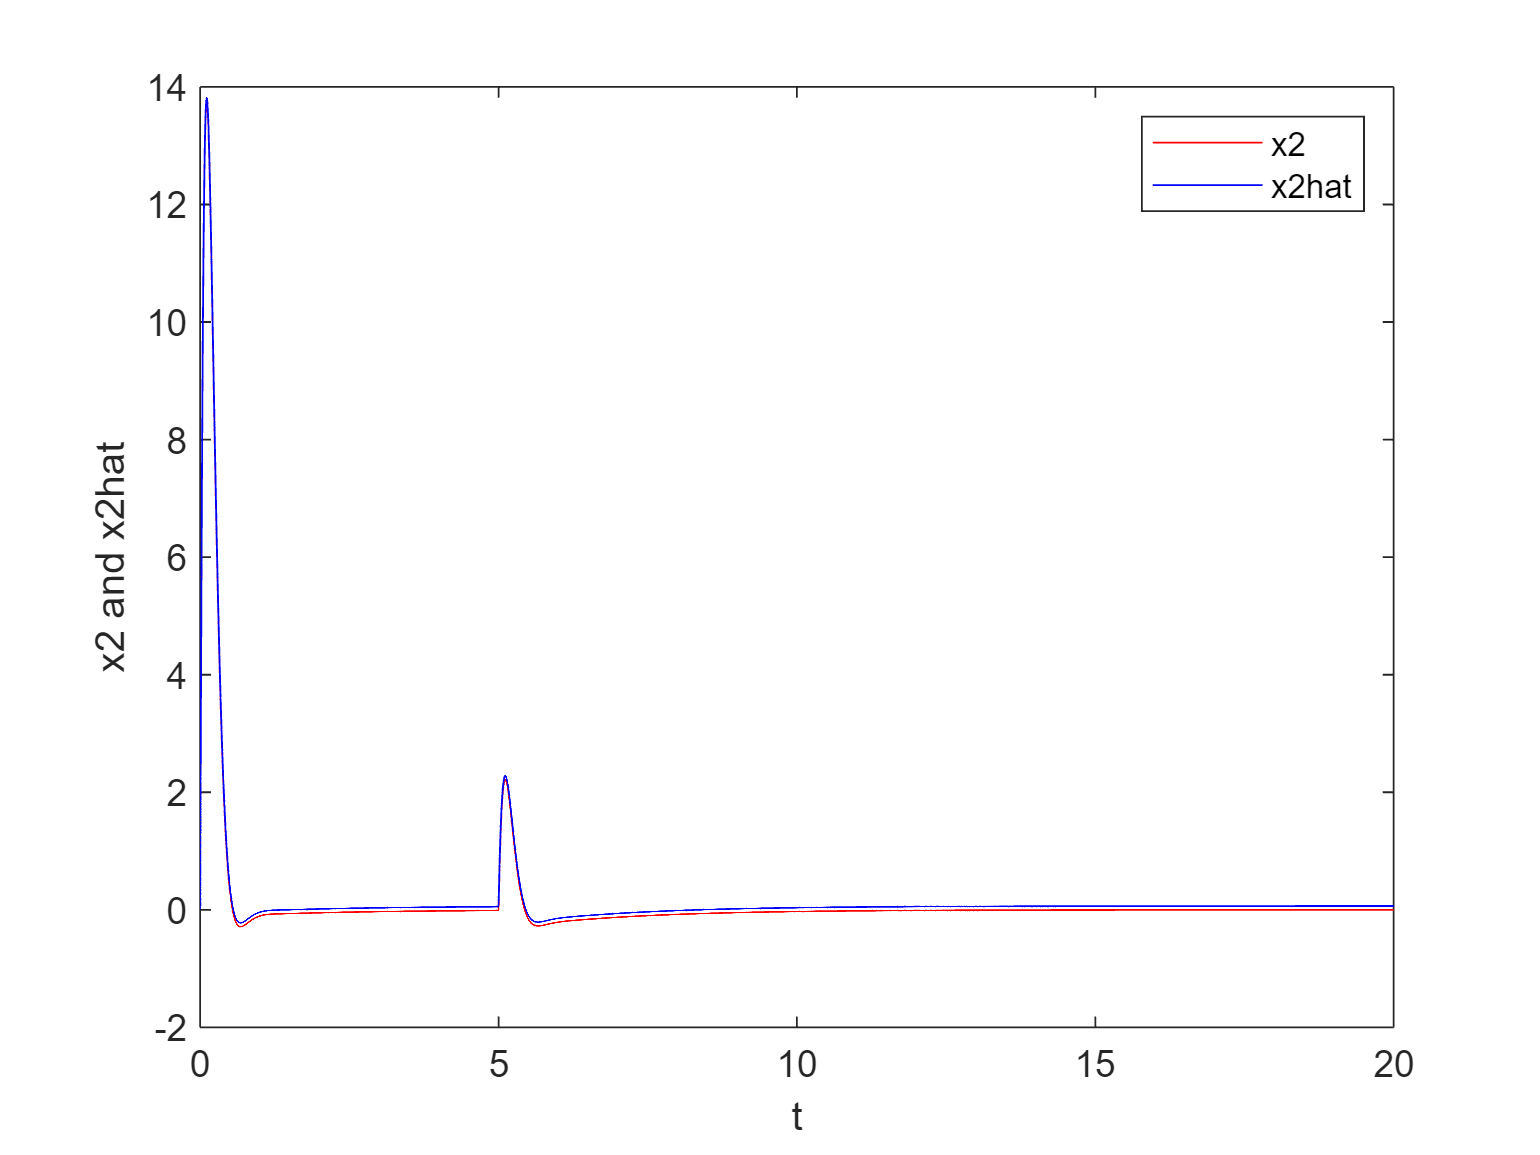

plotDifferences(simOut);

Siamo riusciti ad osservare correttamente il sistema che risulta avere prestazioni comparabili, se non accomunabili, a quelle del sistema controllato sulla base delle variabili reali. Di conseguenza possiamo affermare di essere riusciti a progettare correttamente l'osservatore richiesto.